clear; close all; clc; clf;

pi*(6.19/24)^2

ans = 0.2090



%DesignParameters = [a_0, n, sigma_p, gamma_p, cstar, rho_p, mw_air, gamma_air, A_rocket, R_u, ge]
DesignParameters = [0.03,0.35, 0.001, 1.25, 5210, 0.065, 28.97, 1.4, pi*(6.19/24)^2, 1545.3, 32.2];

%DesignInputs = [r_i, r_o, l_0, Ngrain, mystery_0, A_t0, m_bal, T_b];

% baseline design
DesignInputs = [1, 2.375, 8, 4, 4, 1, 1, 70];

%DesignOutputs = [m_p0, A_tb, t_b, isp_avg, p_cmax, f_max, A_p0/A_t0, ]

%DesignTrajectory = [m_case, m_0, h_bo, v_bo, a_p, h_max, v_max, a_max, a_max/ge]


vacc = 3;

x = thrust_coefficient(1.2,81,10000000000000)

x = 1.9380

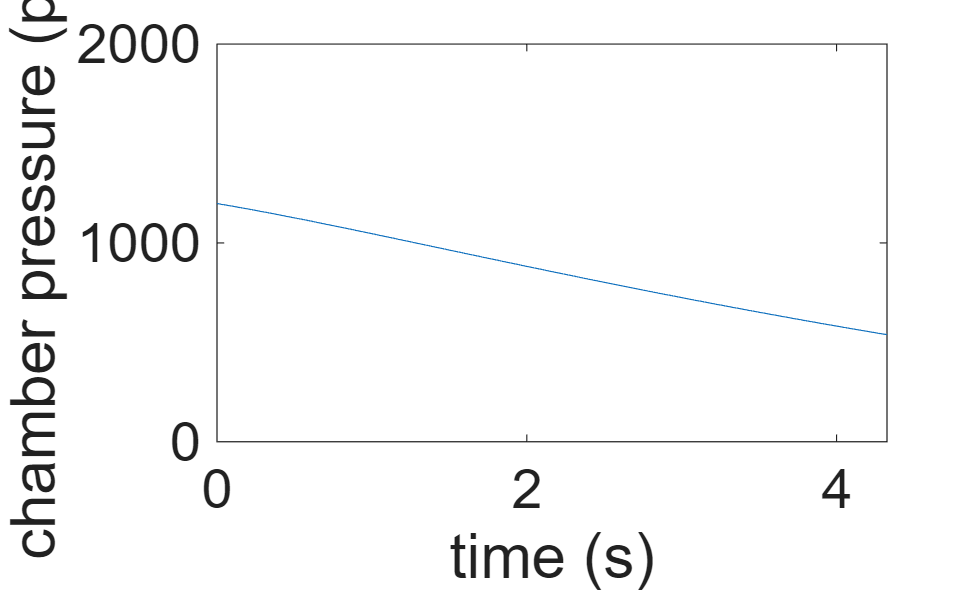

7335.7910298324

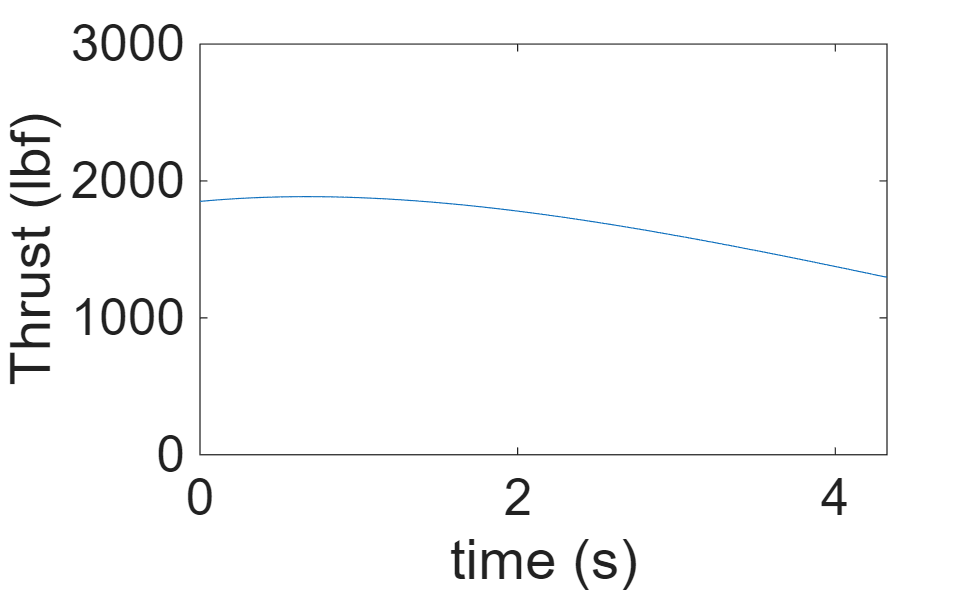

acc =          0   83.3694  719.1387  720.2777  721.3542  722.3638  723.3071  724.1842  724.9955  725.7412  726.3946  726.8758  727.2241  727.4276  727.4746  727.3529  727.3365  727.5232  727.6983  727.8699  728.0462  728.2355  728.1166  727.8742  727.5748  727.2199  726.8106  726.3484  725.8344  725.2700  724.6566  723.9953  723.2876  722.5347  721.7379  720.8986  720.0181  719.0977  718.1387  717.1424  716.1101  715.0431  713.9427  712.8103  711.6470  710.4542  709.2331  707.9850  706.7112  705.4130


vel = 1.0e+03 *

         0         0    0.0023    0.0224    0.0426    0.0628    0.0830    0.1034    0.1237    0.1441    0.1646    0.1851    0.2056    0.2262    0.2468    0.2674    0.2880    0.3087    0.3294    0.3502    0.3710    0.3918    0.4126    0.4335    0.4544    0.4753    0.4962    0.5172    0.5382    0.5592    0.5802    0.6012    0.6222    0.6433    0.6643    0.6854    0.7065    0.7276    0.7487    0.7697    0.7909    0.8120    0.8331    0.8542    0.8753    0.8964    0.9175    0.9387    0.9598    0.9809


height = 1.0e+04 *

         0         0    0.0000    0.0000    0.0001    0.0003    0.0005    0.0007    0.0011    0.0014    0.0019    0.0024    0.0029    0.0035    0.0042    0.0049    0.0057    0.0066    0.0075    0.0084    0.0095    0.0106    0.0117    0.0129    0.0142    0.0155    0.0169    0.0184    0.0199    0.0215    0.0232    0.0249    0.0266    0.0285    0.0304    0.0324    0.0344    0.0365    0.0387    0.0409    0.0432    0.0456    0.0480    0.0505    0.0530    0.0557    0.0584    0.0611    0.0640    0.0669


mach =          0         0         0    0.0118    0.1140    0.2165    0.3192    0.4222    0.5255    0.6290    0.7327    0.8367    0.9409    1.0454    1.1500    1.2548    1.3597    1.4647    1.5699    1.6753    1.7809    1.8866    1.9926    2.0987    2.2049    2.3113    2.4178    2.5244    2.6312    2.7380    2.8450    2.9520    3.0592    3.1664    3.2737    3.3811    3.4885    3.5960    3.7036    3.8113    3.9190    4.0267    4.1345    4.2424    4.3503    4.4582    4.5661    4.6741    4.7822    4.8902


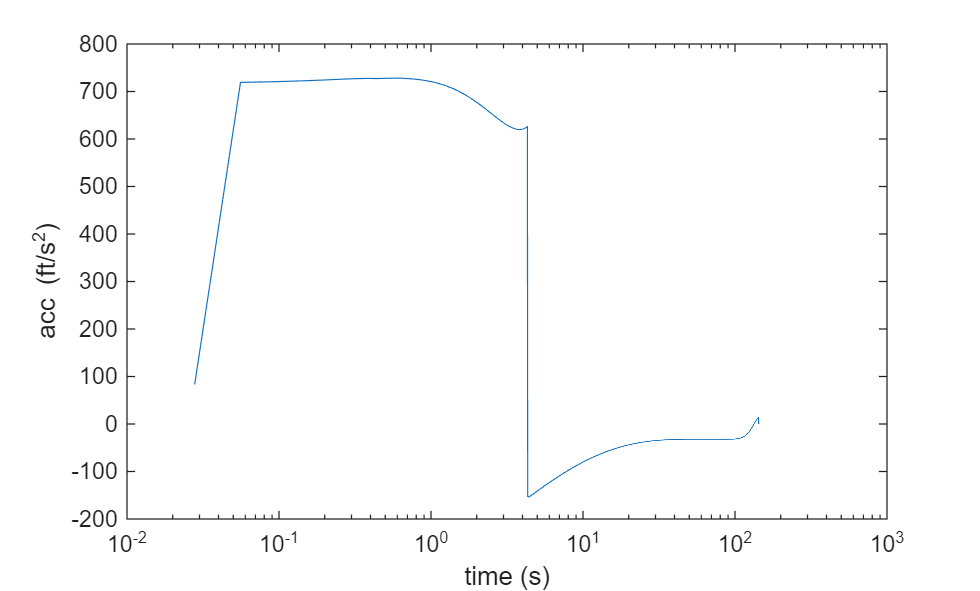

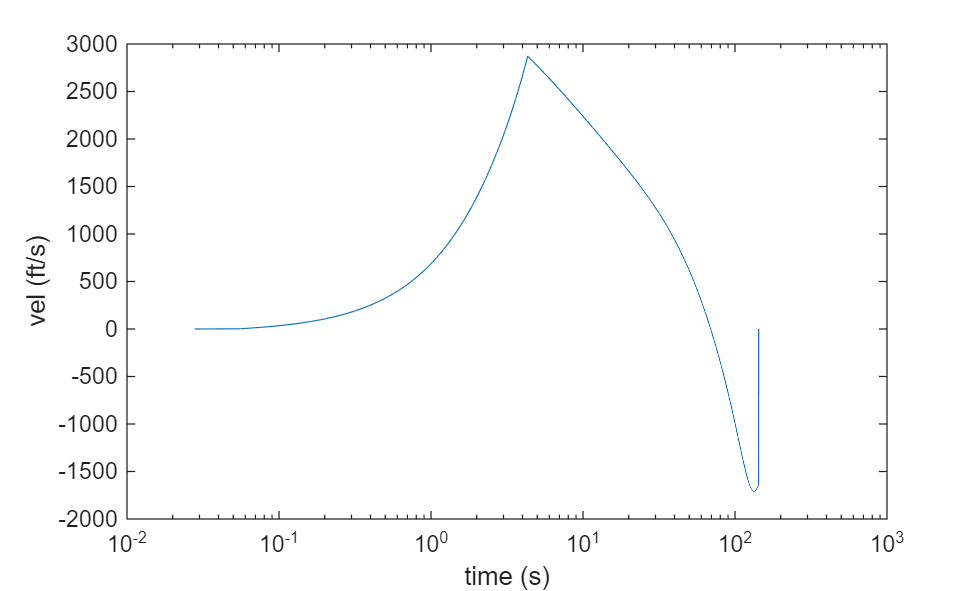

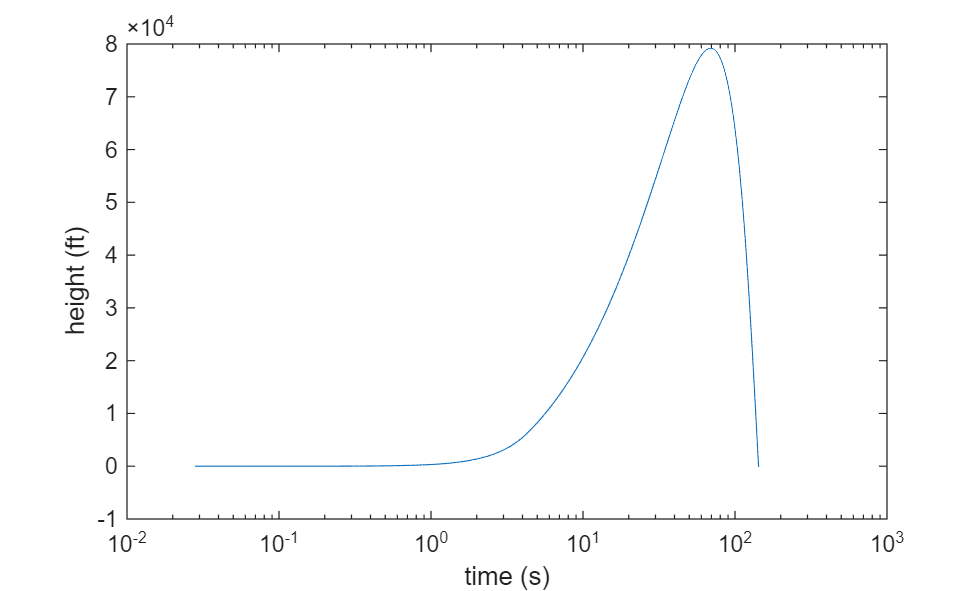



[DesignOutputs,DesignTrajectory,eta,cf] = rocket(DesignInputs,DesignParameters,vacc);

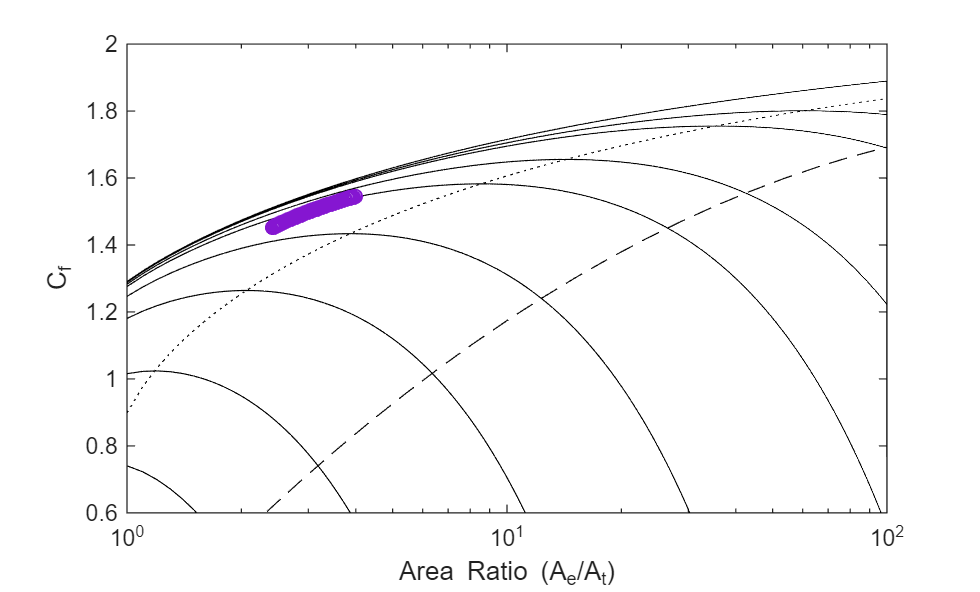

AR = 0:0.1:100;
curve1 = zeros(length(AR),1);
curve2 = zeros(length(AR),1);
curve3 = zeros(length(AR),1);
curve4 = zeros(length(AR),1);
curve5 = zeros(length(AR),1);
curve6 = zeros(length(AR),1);
curve7 = zeros(length(AR),1);
curve8 = zeros(length(AR),1);
curve9 = zeros(length(AR),1);
curve10 = zeros(length(AR),1);
ratioOfTheSpecificHeats = 1.25;

for index = 1:1000
    ratio = index/10;
    curve1(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,2);
    curve2(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,4);
    curve3(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,10);
    curve4(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,25);
    curve5(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,75);
    curve6(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,150);
    curve7(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,500);
    curve8(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,1000);
    curve9(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,100000000);
    curve10(index) = thrust_coefficient_special(ratioOfTheSpecificHeats,ratio);
end




cfmin = @(ar) -0.0445*log(ar).^2 + 0.5324.*log(ar) + 0.1843;
figure(1);
semilogx(AR,curve1,AR,curve2,AR,curve3,AR,curve4,AR,curve5,AR,curve6,AR,curve7,AR,curve8,AR,curve9,'Color','k')
hold on;
semilogx(AR,curve10,':','Color','k')
semilogx(eta,cf,'o')
fplot(cfmin,'--','Color','k');
ylim([0.6 2])
xlim([1 100])
xlabel('Area Ratio (A_e/A_t)')
ylabel('C_f')
hold off;






function [DesignOutputs,DesignTrajectory,eta,cf] = rocket(DesignInputs,DesignParameters,vacc)

    w_step = 0.01;

    Cd =  [0.15 0.15 0.42 0.25 0.175];
    mCd = [0.00 0.60 1.20 1.80 4.000];

    r_i = DesignInputs(1);
    r_o = DesignInputs(2);
    l_0 = DesignInputs(3);
    Ngrain = DesignInputs(4);
    A_e0 = DesignInputs(5);
    A_t0 = DesignInputs(6);
    m_bal = DesignInputs(7);
    T_b = DesignInputs(8);

    a_0 = DesignParameters(1);
    n = DesignParameters(2);
    sigma_p = DesignParameters(3);
    gamma_p = DesignParameters(4);
    cstar = DesignParameters(5); 
    rho_p = DesignParameters(6);
    mw_air = DesignParameters(7);
    gamma_air = DesignParameters(8);
    A_rocket = DesignParameters(9);
    R_u = DesignParameters(10);
    ge = DesignParameters(11);
    

    
    if (l_0/2) < (r_o - r_i)
        wmax = l_0/2;
    else
        wmax = r_o - r_i;
    end

    w = [0:w_step:wmax wmax];
    wlength = length(w);
    
    A_b = Ngrain * pi .* ((r_o^2 - (r_i + w).^2)*2 + ((r_i + w)*2).*(l_0 - 2.* w));
    A_p = pi.*(r_i+w).^2;
    p_c = zeros(1, wlength ); p_c(1) = (a_0 * exp(sigma_p*(T_b-70)) * rho_p * A_b(1) * cstar/(ge * A_t0))^(1/(1-n));         
    A_t = zeros(1,wlength); A_t(1) = A_t0;     
    r = zeros(1,wlength); r(1) = a_0 * exp(sigma_p*(100-70)) * p_c(1)^n;         
    vel = zeros(1,wlength+10000); vel(1) = 0;      
    T_a = zeros(1,wlength); T_a(1) = 518;     
    
    mdot = zeros(1,wlength); mdot(1) = p_c(1) * A_t(1)/cstar;                   
    m_r = zeros(1,wlength); m_r(1) = m_bal +    Ngrain * (r_o^2 - r_i^2) * pi * l_0 + (l_0+0.125) * Ngrain * 0.25 + 40;
    rho_air = zeros(1,wlength+10000); rho_air(1) = 0.07579;
    mach = zeros(1,wlength+10000); mach(1) = 0;
    eta = zeros(1,wlength); eta(1) = A_e0/A_t(1);
    acc = zeros(1,wlength+10000); acc(1) = 0;
    height = zeros(1,wlength+10000); height(1) = 0;
    p_a = ones(1,wlength); 
    
        if vacc == 1
            p_a(1) = 0.0000000000000000000000000000000000000000000000001;
        elseif vacc == 2
            p_a(1) = 14.69241;
        else
            p_a(1) = -4.272981E-14*height(1)^3 + 0.000000008060081*height(1)^2 - 0.0005482655*height(1) + 14.69241; 
        end

    m_p = pi.*(r_o^2 - (r_i+w).^2).* rho_p .* (l_0 - 2.*w) .* Ngrain;
    time = zeros(1,wlength+10000);
    F_t = zeros(1,wlength); F_t(1) = thrust_coefficient(gamma_p,eta(1),p_c(1)/p_a(1)) * A_t(1) * p_c(1);
    I = zeros(1,wlength); 
    d = ones(1,wlength); d(1) = sqrt(A_t0*4/pi);
    cf = zeros(1,wlength); cf(1) = thrust_coefficient(gamma_p,eta(1),p_c(1)/p_a(1));
  
    for i = 1:(length(w)-1)
        
        
        
        p_c(i) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(i) * cstar/(ge * A_t(i)))^(1/(1-n));

        p_c(end) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));

        mdot(i+1) =  p_c(i)* A_t(i)/cstar;

        r(i+1) = a_0 * exp(sigma_p*(T_b-70)) * p_c(i)^n;

        time(i+1) = time(i) + (w(i+1)-w(i))/r(i+1);

        d(i+1) = d(i) + 0.000087 * (time(i+1) - time(i)) * p_c(i);

        A_t(i+1) = pi * 0.25 * d(i+1) * d(i+1);

        eta(i) = A_e0/A_t(i);

        mach(i+1) = vel(i)/sqrt(gamma_air * R_u/mw_air * T_a(i)); 

        if vacc == 1
            p_a(i+1) = 0.0000000000000000000000000000000000000000000000001;
        elseif vacc == 2
            p_a(i+1) = 14.69241;
        else
            p_a(i+1) = -4.272981E-14*height(i)^3 + 0.000000008060081*height(i)^2 - 0.0005482655*height(i) + 14.69241; %0.000000000000000000001; 
        end

        F_t(i) = p_c(i) * A_t(i) * thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        cf(i+1) = thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        acc(i+1) = F_t(i)*ge/m_r(i) - ge - interp1(mCd,Cd,mach(i),'linear','extrap') * 0.5 * rho_air(i) * vel(i) * abs(vel(i)) * A_rocket/m_r(i);

        vel(i+1) = vel(i) + acc(i) * (time(i+1) - time(i));

        height(i+1) = height(i) + (vel(i+1) + vel(i))/2 * (time(i+1) - time(i));

        rho_air(i+1) = 0.00000000001255* height(i)^2 - 0.0000019453*height(i) + 0.07579;

        T_a(i+1) = -0.0036*height(i) + 518;

        %        balast mass             mass of the grains                         case mass                   baseline mass
        m_r(i+1) = (m_bal +    Ngrain * (r_o^2 - (r_i)^2) * pi * l_0 *rho_p + (l_0+0.125) * Ngrain * 0.25 + 40) - mdot(i)*(time(i+1) - time(i));

    end
  
    d(end) = d(end-1) + 0.000087 * (time(end) - time(end-1)) * p_c(end-1);
    A_t(end) = pi * 0.25 * d(end) * d(end);
              
    p_c(end) = (a_0* exp(sigma_p*(T_b-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));
    eta(end) = A_e0/A_t(end);
    F_t(end) = p_c(end) * A_t(end) * thrust_coefficient(gamma_p,eta(end),p_c(end)/p_a(end));

    for i = 1:(length(w)-1)

    I(i+1) = ( F_t(i+1) + F_t(i) )/2 * (time(i+1) - time(i));

    end

    I_total = sum(I);
    fprintf('%10.10f',I_total)
    Isp = I_total/m_p(1);

    
   

    figure(1)
    plot(time(1:length(p_c)),p_c)
    ylim([0 2000])
    ax = gca; % current axes
    ax.FontSize = 24;
    xlabel('time (s)')
    ylabel('chamber pressure (psi)')

    % figure(2)
    % plot(time,A_b)
    % ylim([0 385])
    % ax = gca; % current axes
    % ax.FontSize = 24;
    % xlabel('time (s)')
    % ylabel('burn area (in^2)')
    % 

    figure(3)
    plot(time(1:length(p_c)),F_t)
    xlabel('time (s)')
    ylabel('Thrust (lbf)')
    ylim([0 3000]);
    ax = gca; % current axes
    ax.FontSize = 22;
    

    % figure(4)
    % plot(time,m_p)
    % xlabel('time (s)')
    % ylabel('propelent mass (lbm)')
    % ax = gca; % current axes
    % ax.FontSize = 22;
    % 
    % 
    % figure(5)
    % plot(time,p_c)
    % xlabel('time (s)')
    % ylabel('chamber pressure (psi)')
    % ax = gca; % current axes
    % ax.FontSize = 22;
    % 
    % 
    % figure(6)
    % plot(time,F_t)
    % xlabel('time (s)')
    % ylabel('Thrust (lbf)')
    % ax = gca; % current axes
    % ax.FontSize = 22;
    % 


      
  

    DesignOutputs = [Ngrain * (r_o^2 - r_i^2) * pi * l_0*rho_p 
        A_t(end)
        time(end)
        Isp
        max(p_c)
        max(F_t)
        A_p(1)/A_t(1)
        max(w)];

    for i = (length(w)):1:10000
        

        time(i+1) = time(i) + 0.1;

        


        if mach(i-1) > 4
            acc(i) = - ge - 0.175 * 0.5 * rho_air(i-1) * abs(vel(i-1))* vel(i-1) * A_rocket/m_r(end);
        else
            acc(i) = - ge - interp1(mCd,Cd,abs(mach(i-1))) * 0.5 * rho_air(i-1) * abs(vel(i-1))* vel(i-1) * A_rocket/m_r(end);
        end

        vel(i) = vel(i-1) + acc(i-1) * (time(i) - time(i-1));
        height(i) = height(i-1) + (vel(i) + vel(i-1))/2 * (time(i) - time(i-1));

        T_a(i) = -0.0036 * height(i) + 518;

        mach(i+1) = abs(vel(i))/sqrt(gamma_air * R_u/mw_air * T_a(i));

        if mach(i+1) >4
            mach(i+1) =4;
        end

        rho_air(i) = 0.00000000001255* height(i)^2 - 0.0000019453*height(i) + 0.07579;

        

        if height(i) < 0
            break;
        end





    end

        acc
        vel
        height
        mach

    figure(7)
    semilogx(time,acc)
    xlabel('time (s)')
    ylabel('acc (ft/s^2)')
    figure(8)
    semilogx(time,vel)
    xlabel('time (s)')
    ylabel('vel (ft/s)')
    figure(9)
    semilogx(time,height)
    xlabel('time (s)')
    ylabel('height (ft)')

    m_0 =  m_bal +    Ngrain * (r_o^2 - (r_i)^2) * pi * l_0 *rho_p + (l_0+0.125) * Ngrain * 0.25 + 40;
    m_case = (l_0+0.125) * Ngrain * 0.25 + 40;
    h_bo = height(length(w));
    v_bo = vel(length(w));
    a_bo = acc(length(w));
    h_max = max(height);
    v_max = max(vel);
    a_max = max(acc);

    DesignTrajectory =...
       [m_case
        m_0
        h_bo
        v_bo
        a_bo
        h_max
        v_max
        a_max
        a_max/ge];






end


function [cf] = thrust_coefficient(gamma, areaRatio, pcpa)

    [~,mach] = machNumbers(areaRatio,gamma);

    papc = 1/pcpa;
    pepc = (1+ (gamma-1)/2 * mach^2 )^(-gamma/(gamma-1));

    one = (2*gamma^2)/(gamma-1);
    two = (2/(gamma+1))^((gamma+1)/(gamma-1));
    three = (1 - pepc^((gamma-1)/gamma));
    four = sqrt(one*two*three);
    five = (pepc-papc)*areaRatio;
    cf = four + five;
end

function [cf] = thrust_coefficient_special(gamma,areaRatio)
% Calculate the thrust coefficient using the given parameters
    [~,mach] = machNumbers(areaRatio,gamma);

    pcpe = (1+ (gamma-1)/2*mach^2)^(gamma/(gamma-1));

    pepc = pcpe^(-1);

    papc = pepc;

    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end

function [M_sub, M_super] = machNumbers(areaRatio, gamma)
% machNumbers - Computes the subsonic and supersonic Mach numbers
% corresponding to a given area ratio A/A*

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ) ...
        .^((gamma+1)/(2*(gamma-1))) - areaRatio;

    try
        M_sub = fzero(f, [1e-6, 0.999]); 
    catch
        M_sub = NaN; 
    end

    try
        M_super = fzero(f, [1.0001, 50]); 
    catch
        M_super = NaN;
    end
end
